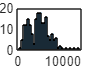

load CrackData.mat;
histogram(crackData.Area, 30);

cutoffregion = 4000;
crackData.Risk = discretize(crackData.Area, [0, cutoffregion, inf], "categorical", ["Mild", "Severe"]);
crackinfo = imageDatastore(crackData.fileName(crackData.Risk == "Severe"));

selectedrows = crackData.Risk == "Severe";
severcrack = crackData(selectedrows, :);
medianvalue = median(severcrack.MaxWidth);

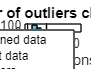

% Fill outliers
[newTable,outlierIndices,thresholdLow,thresholdHigh] = filloutliers(crackData,...
    "linear","DataVariables","NumRegions");

% Display results
figure
[~,binEdges] = histcounts(crackData.NumRegions);
binEdges = unique([binEdges thresholdLow.NumRegions thresholdHigh.NumRegions]);
binEdges = binEdges(isfinite(binEdges));
histogram(newTable.NumRegions,"BinEdges",binEdges,"FaceColor",[0 114 189]/255,...
    "FaceAlpha",1,"DisplayName","Cleaned data")
hold on
histogram(crackData.NumRegions,"BinEdges",binEdges,...
    "FaceColor",[77 190 238]/255,"FaceAlpha",1,"DisplayName","Input data")

% Plot outliers
histogram(crackData.NumRegions(outlierIndices(:,1)),"BinEdges",binEdges,...
    "FaceColor",[217 83 25]/255,"FaceAlpha",1,"DisplayName","Outliers")

% Plot outlier thresholds
plot([thresholdLow.NumRegions*[1 1] NaN thresholdHigh.NumRegions*[1 1]],...
    [ylim missing ylim],"k--","DisplayName","Outlier thresholds")

hold off
title("Number of outliers cleaned: " + nnz(outlierIndices(:,1)))
legend
xlabel("NumRegions")

clear thresholdLow thresholdHigh binEdges